# 该实验进行CBF、Capon、Music、Esprit算法仿真进行DOA估计并且探究在不同阵元数、不同快拍数以及不同信噪比下的DOA估计性能

clc;clear all;close all; 

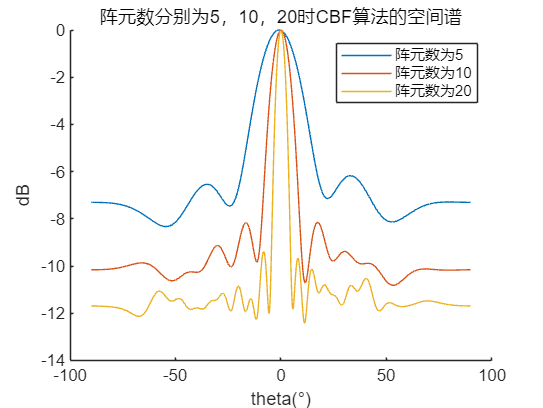


figure;
% 探究阵元数对CBF算法的影响
hold on;
for ArrayNum = [5,10,20]
    CBF(ArrayNum,100,0,[0]);
end
hold off;
legend('阵元数为5','阵元数为10','阵元数为20');
title('阵元数分别为5，10，20时CBF算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

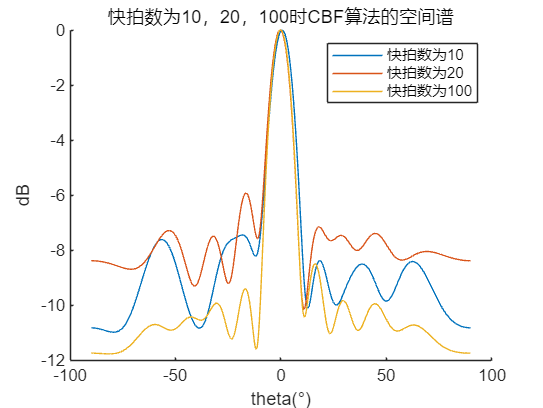


figure;
% 探究快拍数对CBF算法的影响
hold on;
for N = [10,20,100]
    CBF(10,N,0,[0]);
end
hold off;
legend('快拍数为10','快拍数为20','快拍数为100');
title('快拍数为10，20，100时CBF算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

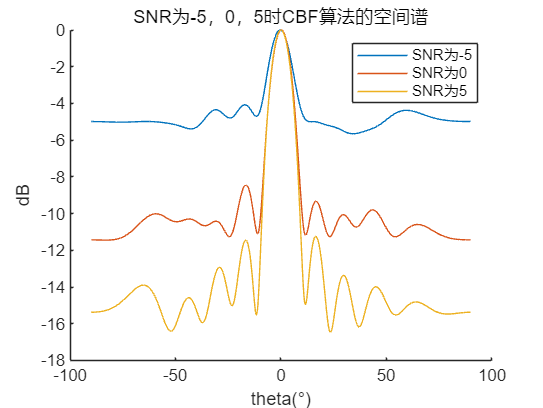


figure;
%探究信噪比对CBF算法的影响
hold on;
for SNR = [-5,0,5]
    CBF(10,100,SNR,[0]);
end
hold off;
legend('SNR为-5','SNR为0','SNR为5');
title('SNR为-5，0，5时CBF算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

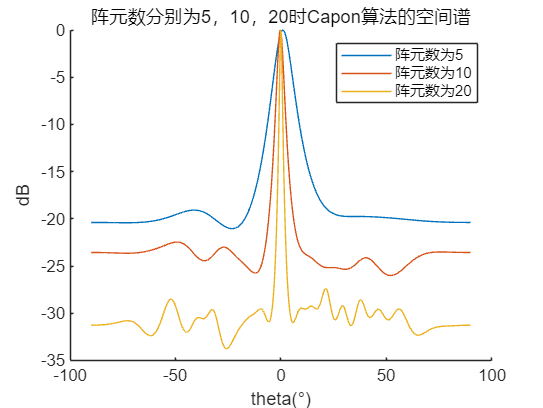


figure;
% 探究阵元数对Capon算法的影响
hold on;
for ArrayNum = [5,10,20]
    Capon(ArrayNum,100,0,[0]);
end
hold off;
legend('阵元数为5','阵元数为10','阵元数为20');
title('阵元数分别为5，10，20时Capon算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

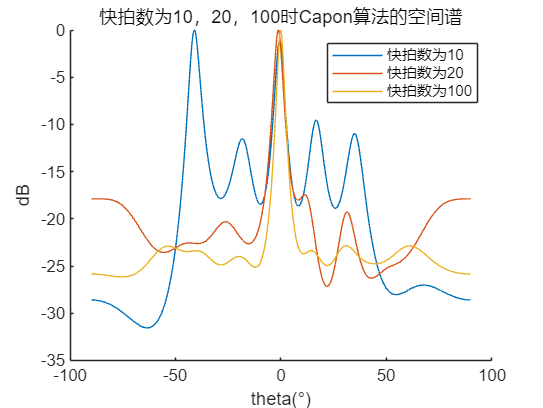


figure;
% 探究快拍数对Capon算法的影响
hold on;
for N = [10,20,100]
    Capon(10,N,0,[0]);
end
hold off;
legend('快拍数为10','快拍数为20','快拍数为100');
title('快拍数为10，20，100时Capon算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

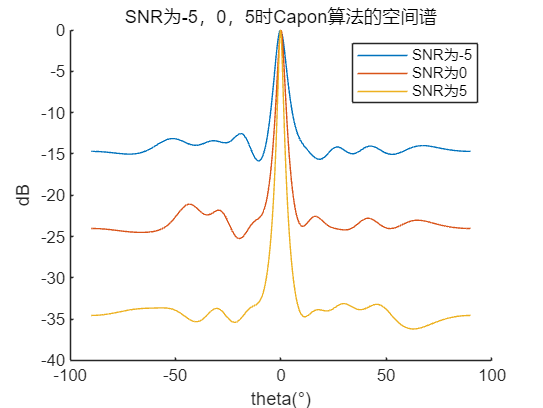


figure;
%探究信噪比对Capon算法的影响
hold on;
for SNR = [-5,0,5]
    Capon(10,100,SNR,[0]);
end
hold off;
legend('SNR为-5','SNR为0','SNR为5');
title('SNR为-5，0，5时Capon算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

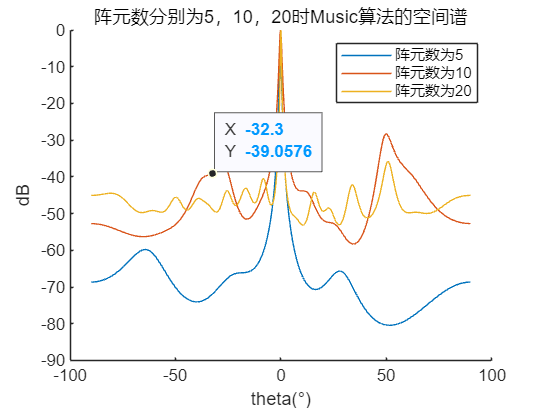

figure;
% 探究阵元数对Music算法的影响
hold on;
for ArrayNum = [5,10,20]
    Music(ArrayNum,100,0,[0]);
end
hold off;
legend('阵元数为5','阵元数为10','阵元数为20');
title('阵元数分别为5，10，20时Music算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

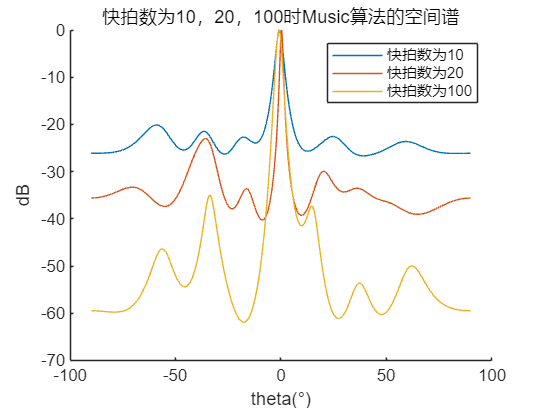


figure;
% 探究快拍数对Music算法的影响
hold on;
for N = [10,20,100]
    Music(10,N,0,[0]);
end
hold off;
legend('快拍数为10','快拍数为20','快拍数为100');
title('快拍数为10，20，100时Music算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

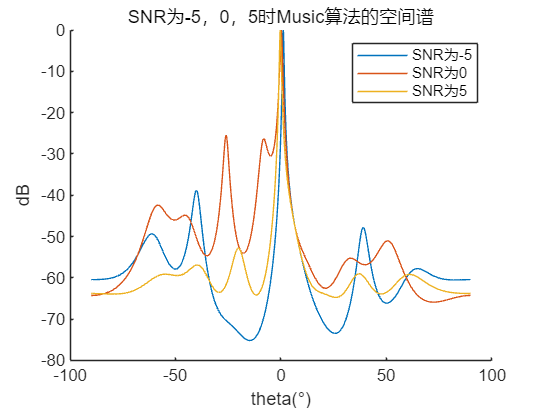


figure;
%探究信噪比对Music算法的影响
hold on;
for SNR = [-5,0,5]
    Music(10,100,SNR,[0]);
end
hold off;
legend('SNR为-5','SNR为0','SNR为5');
title('SNR为-5，0，5时Music算法的空间谱');
xlabel('theta(°)');
ylabel('dB');

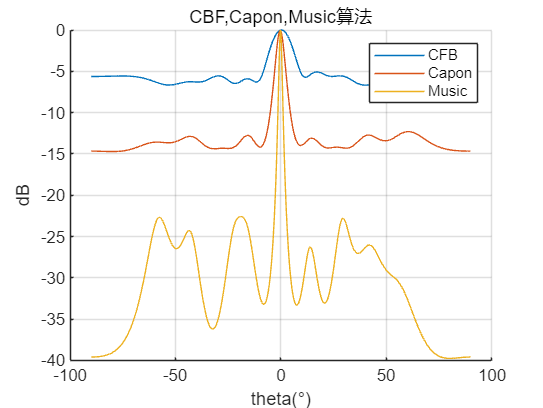

figure;
% 对比CBF,Capon,Music算法
hold on;
CBF(10,100,-5,[0]);
Capon(10,100,-5,[0]);
Music(10,100,-5,[0]);
legend('CFB','Capon','Music');
title('CBF,Capon,Music算法');
xlabel('theta(°)');
ylabel('dB');
grid on;
hold off;

figure;
% 对比CBF,Capon,Music算法多目标情况
hold on;
%CBF(10,50000,5,[0,10,-15]);
Capon(10,50000,5,[0,10,-15]);
Music(10,50000,5,[0,10,-15]);
legend('CFB','Capon','Music');

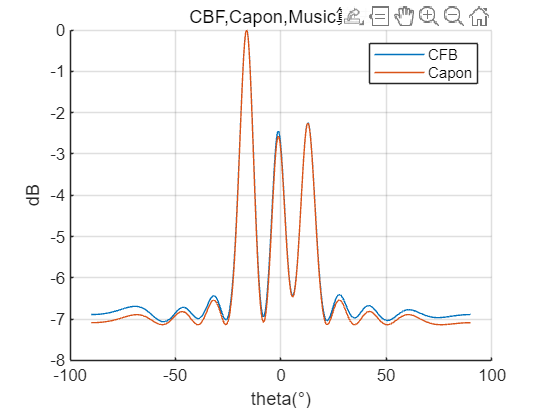

title('CBF,Capon,Music算法');
xlabel('theta(°)');
ylabel('dB');
grid on;
hold off;

function [lambda, d]=parameter()
c = 3e8;             %光速
f0 = 2e9;            %载频
lambda = c/f0;       %波长
d = lambda/2;        %阵元间距
end


function s = GenerateSignal(N, SNR,target_theta)
f0 = 2e9;            %载频
fs = 10e6;           %快时间采样速率（系统带宽）
Ts = 1 / fs;         %采样间隔
t = 0:Ts:(N-1)*Ts;
%% 回波信号为随机信号
s = 10^(SNR/20).*randn(1,N).*ones(1,length(target_theta))'.*exp(1i*2*pi*f0.*t);
end


function X = GenerateX(s, ArrayNum, N, target_theta)
[lambda, d]=parameter();
Noise=randn(ArrayNum, N).*exp(1i*2*pi*rand(ArrayNum,N));
A = exp(-1i*2*pi*d*(0:ArrayNum-1)'*sind(target_theta)/lambda);
X = A*s + Noise;
end


function CBF(ArrayNum,N,SNR,target_theta)
[lambda, d]=parameter();
s = GenerateSignal(N, SNR, target_theta);
X = GenerateX(s, ArrayNum, N, target_theta);

Theta = -90:0.1:90;
a = exp(-1i*2*pi*d*(0:ArrayNum-1)'*sind(Theta)/lambda);
Rxx = (1/N)*X*X';
P = abs(diag(a' * Rxx * a));
plot(Theta, 10*log10(P/max(P)));
xlabel('theta(°)');
ylabel('方位谱图(dB)');
end


function Capon(ArrayNum, N, SNR, target_theta)
[lambda, d]=parameter();
s = GenerateSignal(N, SNR, target_theta);
X = GenerateX(s, ArrayNum, N, target_theta);
%% 求x的相关矩阵逆
Rxx = (1/N).*X * X';
Rxx_inv = inv(Rxx);

Theta = -90:0.1:90;
a = exp(-1i*2*pi*(0:ArrayNum-1)'*d*sind(Theta)/lambda);
P_Capon = abs(diag(1./(a'*Rxx_inv*a)));
%music = abs(diag(1./(a_omega'*(Un*Un')*a_omega)));
P_Capon = 10*log(P_Capon/max(P_Capon));

plot(Theta, P_Capon);
title('Capon算法');
xlabel('Theta(°)');
end


function Music(ArrayNum, N, SNR, target_theta)
[lambda, d]=parameter();
s = GenerateSignal(N, SNR, target_theta);
X = GenerateX(s, ArrayNum, N, target_theta);
%% 计算相关系数
Rxx = (1/N)*X*X';
[U,V] = eig(Rxx);
V = diag(V);
[V,idx] = sort(V,'descend');
U = U(:,idx);
P = sum(V);
P_cum = cumsum(V);

J = find(P_cum/P>=0.9);
J = J(1);
Un = U(:,J+1:end);

theta = -90:0.1:90;

a = exp(-1i*2*pi*(0:ArrayNum-1)'*d*sind(theta)/lambda);
music = abs(diag(1./(a'*(Un*Un')*a)));
music = 10*log(music/max(music));

plot(theta, music);
title('Music算法');
xlabel('Theta(°)');
end


function Esprit(ArrayNum, N, SNR, target_theta)
K = length(target_theta); 
s = GenerateSignal(N, SNR, target_theta);
X = GenerateX(s, ArrayNum, N, target_theta);
Rxx = (1/N)*X*X';

[U, D] = eig(Rxx);
[D, idx] = sort(diag(D));
U = fliplr(U(:, idx));
Us = U(:, 1:K);

Ux = Us(1:ArrayNum-1, :);
Uy = Us(2:ArrayNum, :);

Uxy = [Ux, Uy];
Uxy = Uxy'*Uxy;
[U_xy, D_xy] = eig(Uxy);


[D_xy, idx_xy] = sort(diag(D_xy));
F = fliplr(U_xy(:, idx_xy));
F0 = F(1:K, K+1:K*2);
F1 = F(K+1:K*2, K+1:K*2);
Psi = -F0/F1;

[T,Phi] = eig(Psi);
Theta = asind(-angle(diag(Phi))/pi);             % 估计角度
Theta = sort(Theta).';
disp('估计结果：');
disp(Theta);

end